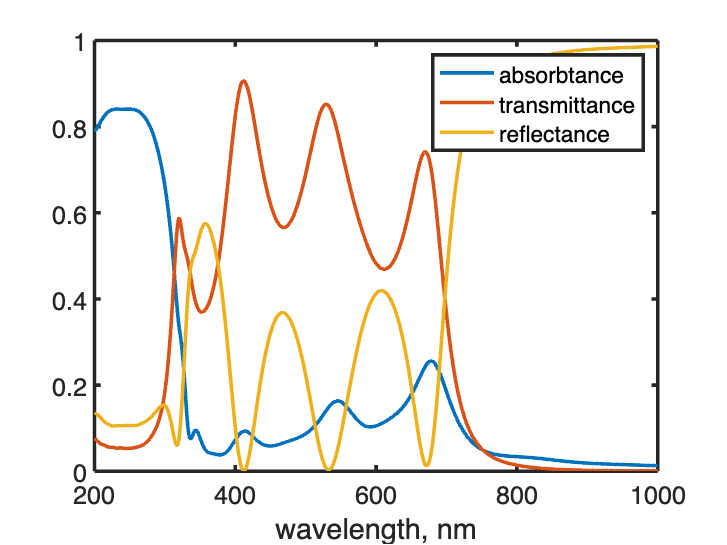

% Example script demonstrating how to calculate ATR and reproducing 
% transmittance of a multilayered stack in Figure 2 from the reference:
% M. Scalora, M. J. Bloemer, A. S. Pethel, J. P. Dowling, C. M. Bowden, A. S. Manka; 
% Transparent, metallo-dielectric, one-dimensional, photonic band-gap structures. 
% J. Appl. Phys. 1 March 1998; 83 (5): 2377–2383. 
% https://doi.org/10.1063/1.366996
% -------------------------------------------------------------------------
%% INPUT DATA
% -------------------------------------------------------------------------
% wavelengths of interest
wavelengths = linspace(200, 1000, 801);
theta = 0;
materials = ["air","Ag_JC","const=1.422","Ag_JC","const=1.422","Ag_JC","const=1.422","Ag_JC","air"];
thicknesses = [10,110,10,110,10,110,10];
stack = set_stack( materials, thicknesses, wavelengths, theta );
% -------------------------------------------------------------------------
%% GETTING ABSORBANCE, TRANSMITTANCE, AND REFLECTANCE
% -------------------------------------------------------------------------
[A,T,R] = ATR1D( stack );
% -------------------------------------------------------------------------
%% PLOTTING RESULTS
% -------------------------------------------------------------------------
figure();
plot(wavelengths,A.sp,wavelengths,T.sp,wavelengths,R.sp,'LineWidth',2);
legend('absorbtance','transmittance','reflectance');
set(gca,'FontSize',14)
xlim([200 1000]); ylim([0 1]);
xlabel('wavelength, nm','FontSize',16)

% -------------------------------------------------------------------------